cd POLIMI/'2-1) NUMERICAL ANALYSIS'/na_tex/matlab/
addpath("./utils")

close all
clear all
clc



































close all
clear all
clc

% Consider the function f(x) = cos(x²)+3 on the interval [1, 19] 
% and assume to employ the bisection method to approximate the zero of such a function. 
% Compute the number of iterations to be performed in order to ensure an accuracy 
% TOL = 1e-4 on the approximation.

a = 1;
b = 19;
TOL = 1e-4;
ceil(log((b-a)/TOL)/log(2)-1)

ans = 17


f = @(x) cos(x.^2)+3;
[x, x_iter] = bisection(f,a,b,TOL);
numel(x_iter)

ans = 18

close all
clear all
clc

five = 5*ones(5,1);
A = spdiags([five five five five five],[-4 -3 -2 -1 0],5,5);
full(A);

[L, U, ~] = lu(A);
full(L)

ans =      1     0     0     0     0
     1     1     0     0     0
     1     1     1     0     0
     1     1     1     1     0
     1     1     1     1     1


full(U)

ans =      5     0     0     0     0
     0     5     0     0     0
     0     0     5     0     0
     0     0     0     5     0
     0     0     0     0     5


close all
clear all
clc

% Consider the function f(x)=sin(x)*sqrt(x+0.5) in the interval I=[-0.5,1] 
% and the associated Lagrange interpolating polynomial, L, based on 6 equispaced interpolation nodes.
% Select the correct sentence:

f = @(x) sin(x).*sqrt(x+0.5);
a = -0.5;
b = 1;

n = 5;
x_nodes = linspace(a,b,n+1);
y_nodes = f(x_nodes);

coeff = polyfit(x_nodes,y_nodes,n);

polyval(coeff,1)

ans = 1.0306


f(0.4)-polyval(coeff,0.4)

ans = -1.1102e-16


polyval(coeff,0.4)

ans = 0.3694


f(-0.25)-polyval(coeff,-0.25)

ans = -0.0045


f(-0.2)-polyval(coeff,-0.2)

ans = 6.9389e-17


x_nodes

x_nodes =    -0.5000   -0.2000    0.1000    0.4000    0.7000    1.0000


f = @(x) log(x)*(x-1)^3 ;
df1 = @(x) (1/x)*(x-1)^3+3*log(x)*(x-1)^2;
df2 = @(x) (-)




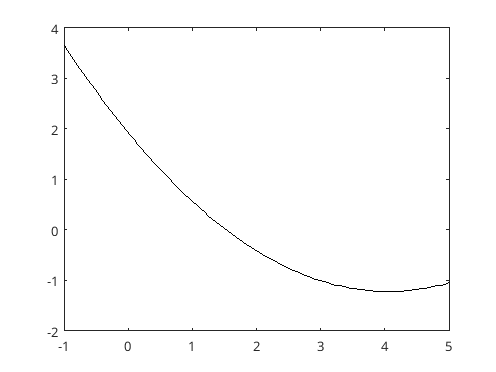

close all
clear all
clc


x_nodes = [0.75 0.75 1.50  2.25  3.00];
y_nodes = [1.00 0.73 0.07 -0.63 -0.99];


coeff = polyfit(x_nodes, y_nodes, 2);
x_plot = linspace(-1,5);
plot(x_plot,polyval(coeff,x_plot),"k-")

polyval(coeff,3.5)

ans = -1.1570